tt = [0 1 2 3 4 5 6 7 8 9]; % hrs
vv = [13.5521	8.5037	6.8038	4.3123	3.3543	3.8569	2.9397	1.1442	1.7904	0.6489]; % V
figure;
clf;
plot(tt, vv, 'ko', 'DisplayName','Data')
xlabel("Time (hrs)")
ylabel("Battery Voltage (V)")
grid('on')
title ("Battery Discharge")

Vo = 13.5;  % V
k = 0.5;    % V
b = 0;
c = 0;
params0 = [Vo, k, b, c];
[beta,R,J,CovB,MSE,ErrorModelInfo] = nlinfit(tt, vv, @batt_model, params0)

beta =    -0.5626    0.8863  -13.6634   13.5349


R =     0.0172
   -0.1817
    0.5841
   -0.5042
   -0.5300
    0.6971
    0.4132
   -0.7890
    0.4332
   -0.1400


J =          0         0         0    1.0000
    8.6194   -3.3998    0.3308    1.0000
   13.0018   -2.9934    0.4671    1.0000
   15.4957   -1.9687    0.5233    1.0000
   17.1525   -1.1467    0.5464    1.0000
   18.4401   -0.6242    0.5559    1.0000
   19.5657   -0.3252    0.5599    1.0000
   20.6203   -0.1643    0.5615    1.0000
   21.6440   -0.0811    0.5622    1.0000
   22.6542   -0.0394    0.5624    1.0000


CovB =     0.0362   -0.0523   -1.3115   -0.0136
   -0.0523    0.1028    1.8788    0.0554
   -1.3115    1.8788   48.8398   -0.1705
   -0.0136    0.0554   -0.1705    0.3925


MSE = 0.3993

ErrorModelInfo = struct with fields:
              ErrorModel: 'constant'
         ErrorParameters: 0.6319
           ErrorVariance: @(x)mse*ones(size(x,1),1)
                     MSE: 0.3993
          ScheffeSimPred: 4
          WeightFunction: 0
            FixedWeights: 0
    RobustWeightFunction: 0


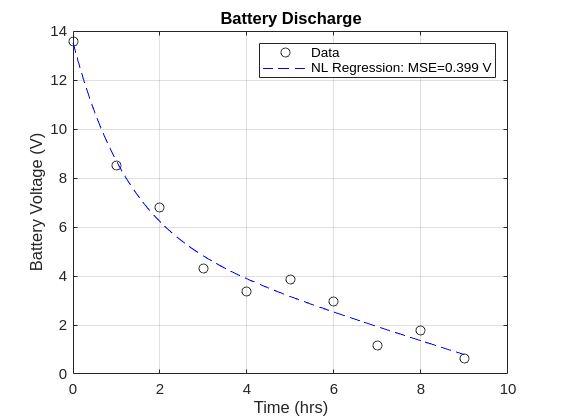


function v = batt_model(params, t)
    Vo = params(1);
    k = params(2);
    b = params(3);
    c = params(4);

    v = Vo*(t-b).*(1-exp(-k*t))+c;
end

tt_reg = linspace(min(tt), max(tt), 100);
vv_reg = batt_model(beta, tt_reg);
hold on
plot(tt_reg, vv_reg, 'b--', 'DisplayName',sprintf('NL Regression: MSE=%.3f V',MSE))
legend()